# PLL demo (multiplier phase detector + LPF + NCO/VCO)

clear; close all; clc;

## 1) Setup: sampling, input signal (slowly varying / almost constant)


fs = 20e3;                 % sample rate (Hz)
T  = 0.5;                  % duration (s)
t  = (0:1/fs:T-1/fs).';

f0 = 1000;                 % nominal input frequency (Hz)
df = 2;                    % small frequency offset (Hz) -> "not changing fast"
fin = f0 + df;             % you can later make this slowly time-varying

phi_in0 = 0.3;             % initial phase offset (rad)
x = cos(2*pi*fin*t + phi_in0);   % input/reference

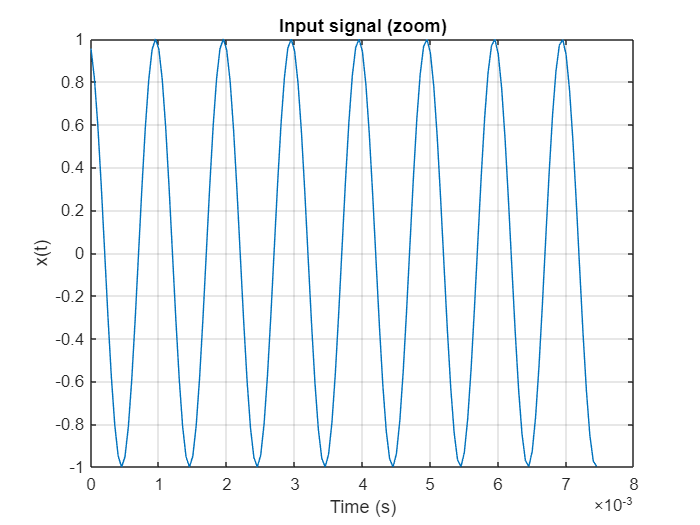

figure('Name','Input signal');
plot(t(1:150), x(1:150));
xlabel('Time (s)'); ylabel('x(t)'); grid on; title('Input signal (zoom)');

## 2) VCO/NCO block: start near the right frequency but with some error

f_vco0 = 990;              % initial VCO frequency guess (Hz)
phi_vco = 0;               % VCO phase accumulator (rad)

% NCO gain: how strongly control signal shifts frequency
Kvco = 50;                % Hz per 1 "control unit" (tuning knob)

% Preallocate
N = numel(t);
y_vco  = zeros(N,1);       % VCO output
f_vco  = zeros(N,1);       % instantaneous VCO frequency (Hz)

## 3) Phase detector: multiplier (mixer)

% PD output: e = x * y_vco
e_pd = zeros(N,1);

## 4) Loop filter: 1st-order low-pass (IIR)

% u[n] = (1-a)*e_pd[n] + a*u[n-1]
% smaller a -> wider bandwidth (faster lock), larger a -> smoother (slower)
a = 0.995;                 % tuning knob
u = zeros(N,1);            % filter output (control signal)

## 5) Run PLL

for n = 2:N
    % VCO output at current phase
    y_vco(n) = cos(phi_vco);

    % Phase detector (multiplier)
    e_pd(n) = x(n) * y_vco(n);

    % Loop low-pass filter
    u(n) = (1-a)*e_pd(n) + a*u(n-1);

    % Update VCO frequency from control
    f_vco(n) = f_vco0 + Kvco * u(n);

    % Integrate phase (NCO)
    phi_vco = phi_vco + 2*pi*(f_vco(n)/fs);

    % Keep phase bounded for numerical neatness
    if phi_vco > 1e5
        phi_vco = mod(phi_vco, 2*pi);
    end
end

## 6) Visualize each block's signal (what each part is doing)

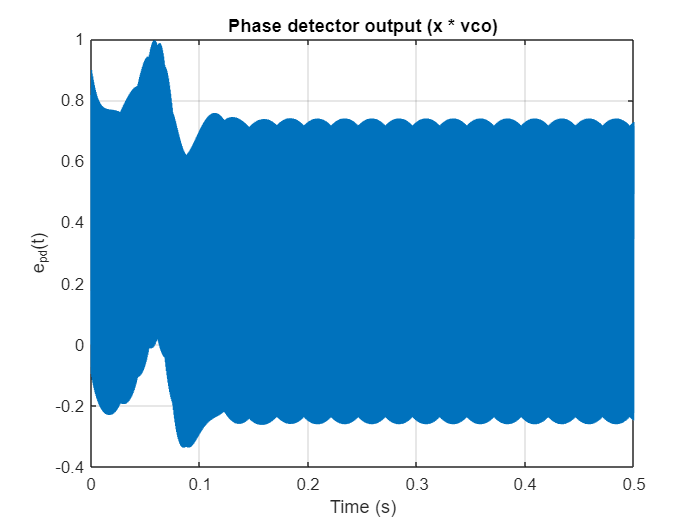

% PD output contains a high-frequency term and a low-frequency term.
figure('Name','Phase detector output');
plot(t, e_pd); grid on;
xlabel('Time (s)'); ylabel('e_{pd}(t)'); title('Phase detector output (x * vco)');

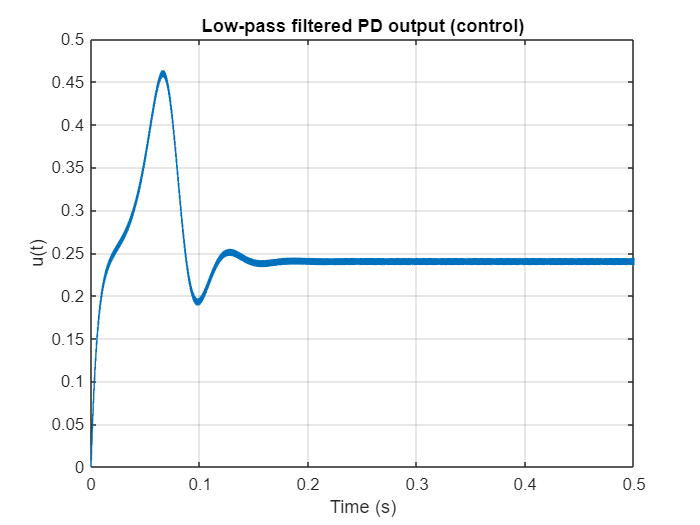


figure('Name','Loop filter output (control)');
plot(t, u); grid on;
xlabel('Time (s)'); ylabel('u(t)'); title('Low-pass filtered PD output (control)');

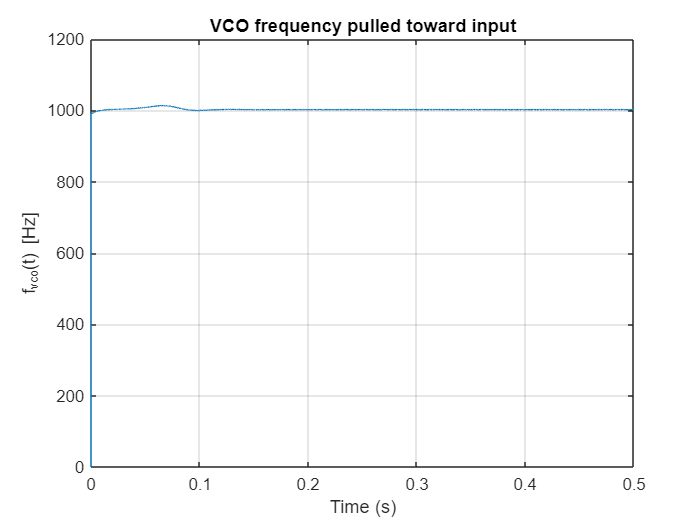


figure('Name','VCO frequency');
plot(t, f_vco); grid on;
xlabel('Time (s)'); ylabel('f_{vco}(t) [Hz]'); title('NCO frequency pulled toward input');

## 7) "Are we locked?" check: phase error estimate (simple, visual)

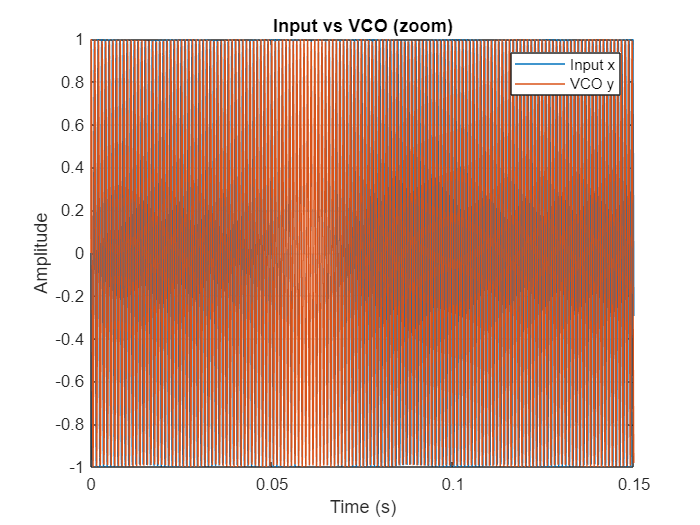

% For a multiplier PLL with cosine signals, after LPF:
% u ~ 0.5*cos(phase_error) (plus scaling). Not linear, but good for intuition.
figure('Name','Compare input vs NCO (zoom)');
idx = 1:3000;
plot(t(idx), x(idx)); hold on; plot(t(idx), y_vco(idx));
grid on; xlabel('Time (s)'); ylabel('Amplitude');
legend('Input x','VCO y'); title('Input vs NCO (zoom)');